% TODOS:
% Implement MSER
addpath("backend/")

reference = rgb2gray(imread("images/box.jpg"));
target = rgb2gray(imread("images/scene.jpg"));
reference = selectAndCrop(reference);

 
detectionMethod = "SURF";

referencePoints = encodedFeatures(detectionMethod, reference);
targetPoints = encodedFeatures(detectionMethod, target);

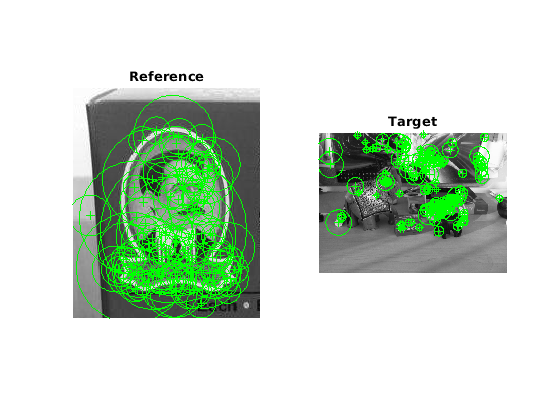

subplot(1,2,1)
imshow(reference);
hold on;
title('Reference');
plot(selectStrongest(referencePoints, 100));
hold off;

subplot(1,2,2)
imshow(target);
hold on;
title('Target');
plot(selectStrongest(targetPoints, 100));
hold off;

[matchedReferencePoints, matchedTargetPoints] = matchingPoints( ...
    reference, referencePoints, ...
    target, targetPoints);

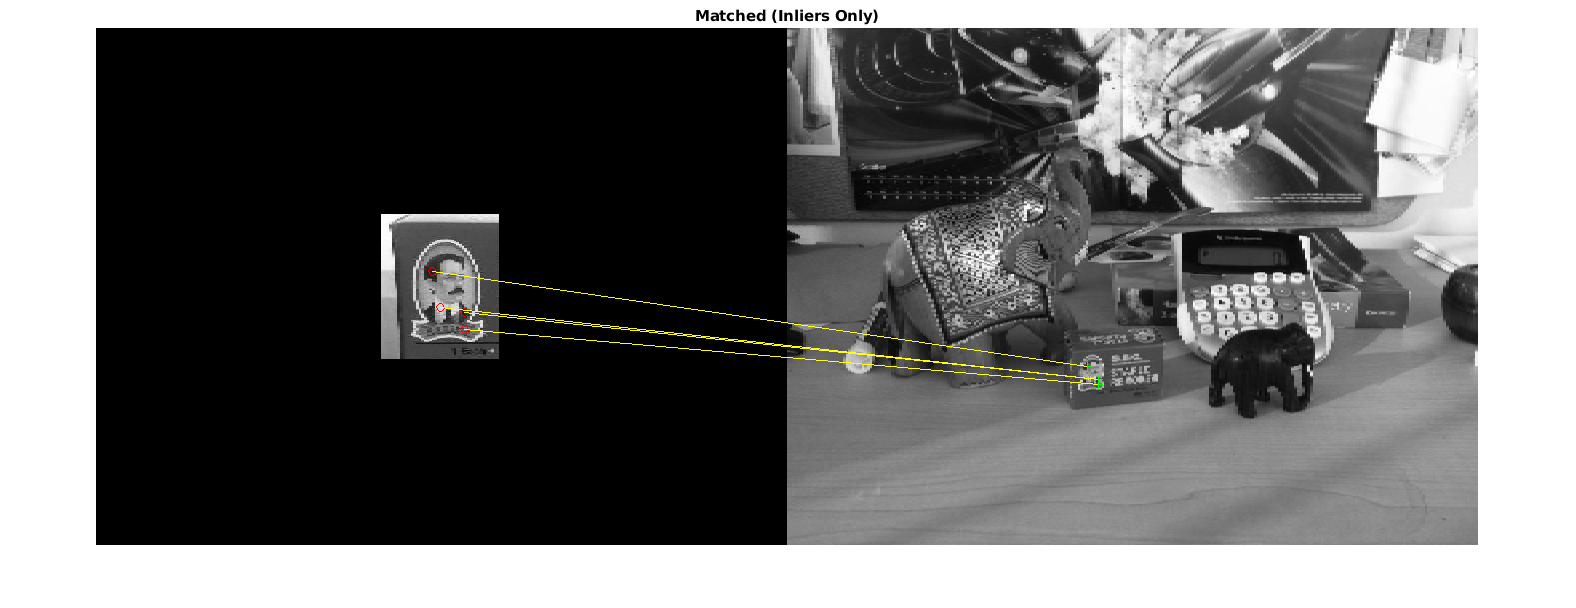

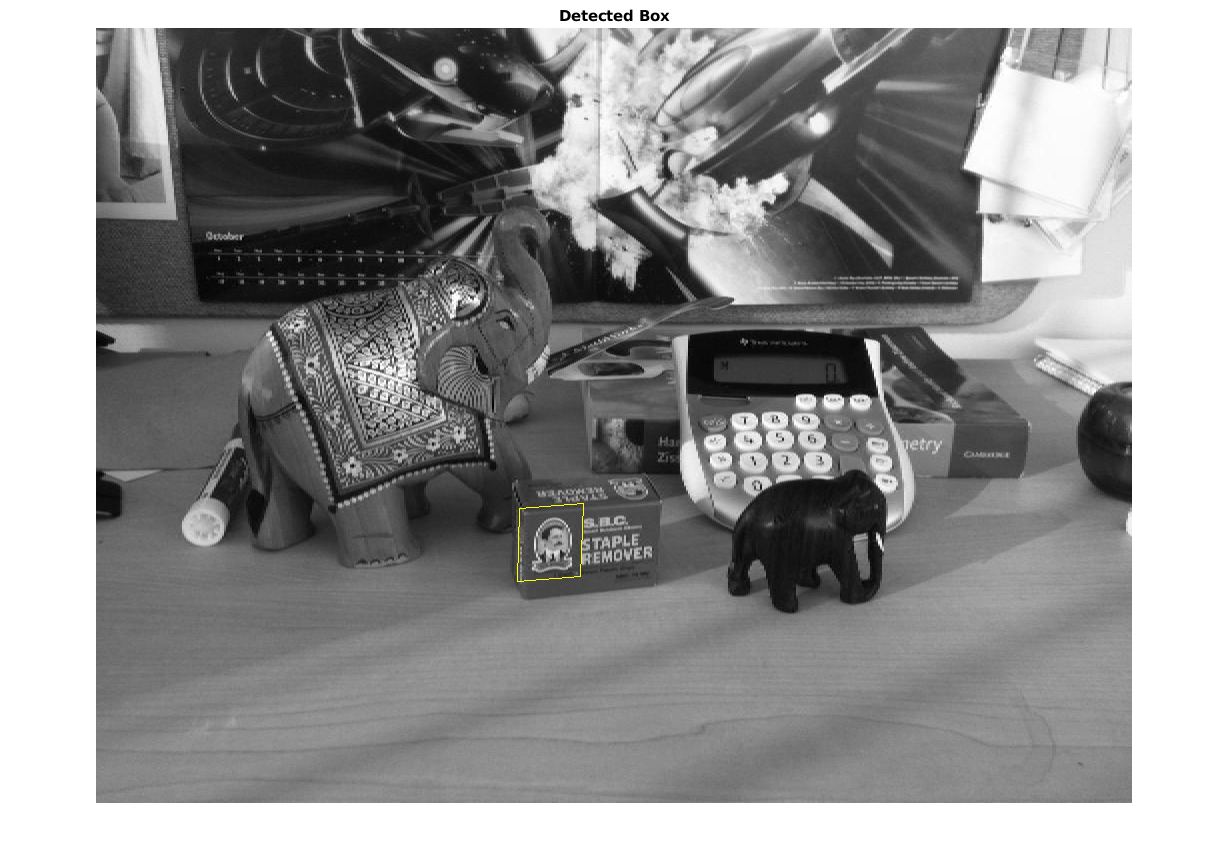

if((matchedTargetPoints.length > 2) && (matchedReferencePoints.length > 2))
    [tform, estimatedReferencePoints, estimatedTargetPoints] = ...
        estimateGeometricTransform(matchedReferencePoints, matchedTargetPoints, 'affine');
    
    figure;
    showMatchedFeatures(reference, target, estimatedReferencePoints, ...
        estimatedTargetPoints, 'montage');
    title('Matched (Inliers Only)');
    
    foundPolygon = [1, 1;...                                    % top-left
                size(reference, 2), 1;...                    % top-right
                size(reference, 2), size(reference, 1);...    % bottom-right
                1, size(reference, 1);...                    % bottom-left
                1, 1];                                      % top-left again to close the polygon

    newFoundPolygon = transformPointsForward(tform, foundPolygon);
    
    figure;
    imshow(target);
    hold on;
    line(newFoundPolygon(:, 1), newFoundPolygon(:, 2), 'Color', 'y');
    title('Detected Box');
    hold off;
else
    disp("Not enough features found for matching.")
end